
close all
clear all
colors=npg(10); % Ten basic colors

delta_f = [];

% date_file.date = {'2026-07-28','2026-07-29', ...
%     '2026-07-30','2026-07-31'};
% date_file.file = {[497 660]; ...   % 与日期一一对应
%     [552 678];
%     [670];[546 618]; ...
%     };

date_file.date = {'2026-08-04','2026-08-05','2026-08-06',...
    '2026-08-07'};
date_file.file = {[607];[702];[621]; ...   % 与日期一一对应
    [342 646]};

maindir0 = '\\Artemis-pc\Data\';

for k1 = 1:length(date_file.date)
    for k2 = 1:length(date_file.file{k1})
        maindir = [maindir0,date_file.date{k1}, ...
            '\Abs-',num2str(date_file.file{k1}(k2))];
        load([maindir,'\diffR.mat'],'df');
        %delta_f = [delta_f,dfm];
        %err_f = [err_f,dfs];
        delta_f = [delta_f,df];
    end
end

df_m = mean(delta_f);
df_std = std(delta_f)/sqrt(length(delta_f)-1);

f1 = figure; hold on;
box on;
plot([1:length(delta_f)],delta_f,'.', ...
    'MarkerSize',14,'Color',[0.23 0.61 0.82]);
ylabel('df (mHz)');
set(gca,'FontName','times new roman',...
    'FontSize',16);
xlim([0 length(delta_f)+1]);

n1 = [1 2 3 4];
patch_list = [0 df_m-df_std ; length(delta_f)+1 df_m-df_std; ...
    length(delta_f)+1 df_m+df_std ; 0 df_m+df_std];
patch('Faces',n1,'Vertices',patch_list,...
    'FaceAlpha',0.3,'FaceColor',[0.74 0.89 1],'EdgeColor','none');
plot([0 length(delta_f)+1],[df_m df_m], ...
    Color=[0.36 0.53 0.65],LineWidth=2);

legend(['\delta\omega = 2\pi\times', ...
    num2str(df_m,'%.3f'),'(',num2str(df_std*1e3,'%.0f'),') mHz'], ...
    '','','Location','best');

set(f1,'Visible','on');

save([maindir0,date_file.date{end},'\df_total.mat']);

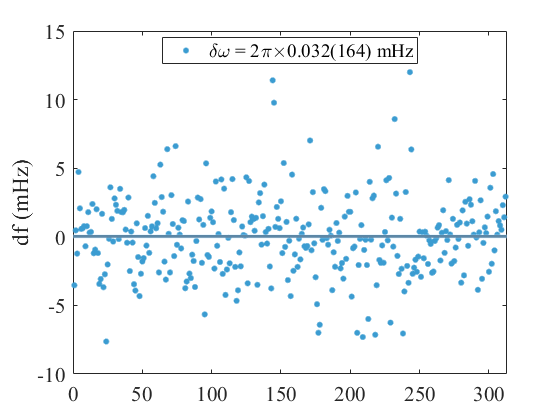

savefig(f1,[maindir0,date_file.date{end},'\df_total.fig']);
saveas(f1,[maindir0,date_file.date{end},'\df_total.png']);


% weight_f = 1./err_f.^2;
% df_m = sum(delta_f* weight_f)/sum(weight_f);
% df_std = sqrt(sum(weight_f.* ((delta_f-df_m).^2)) / sum(weight_f));
% 
% % 计算 Chi square %
% chi_square = 0;
% for k1 = 1:length(delta_f)
%     temp(k1) = ( delta_f(k1)-df_m )^2;
%     chi_square = chi_square + weight_f(k1)*temp(k1);
% end
% chi_square = chi_square/(length(delta_f)-1);
